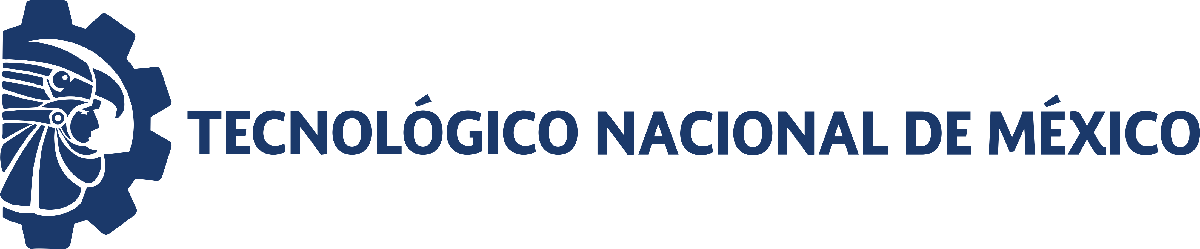                                 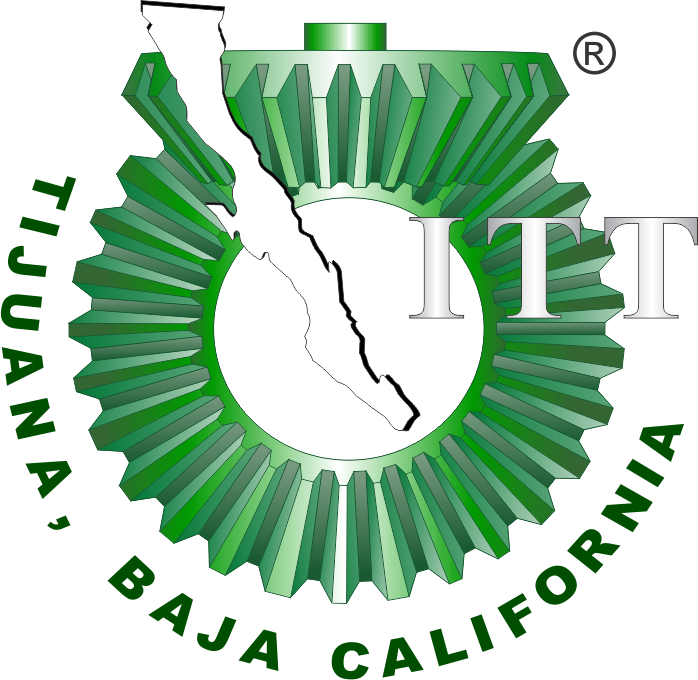

# Práctica dos: Sistema cardiovascular

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

                                                                            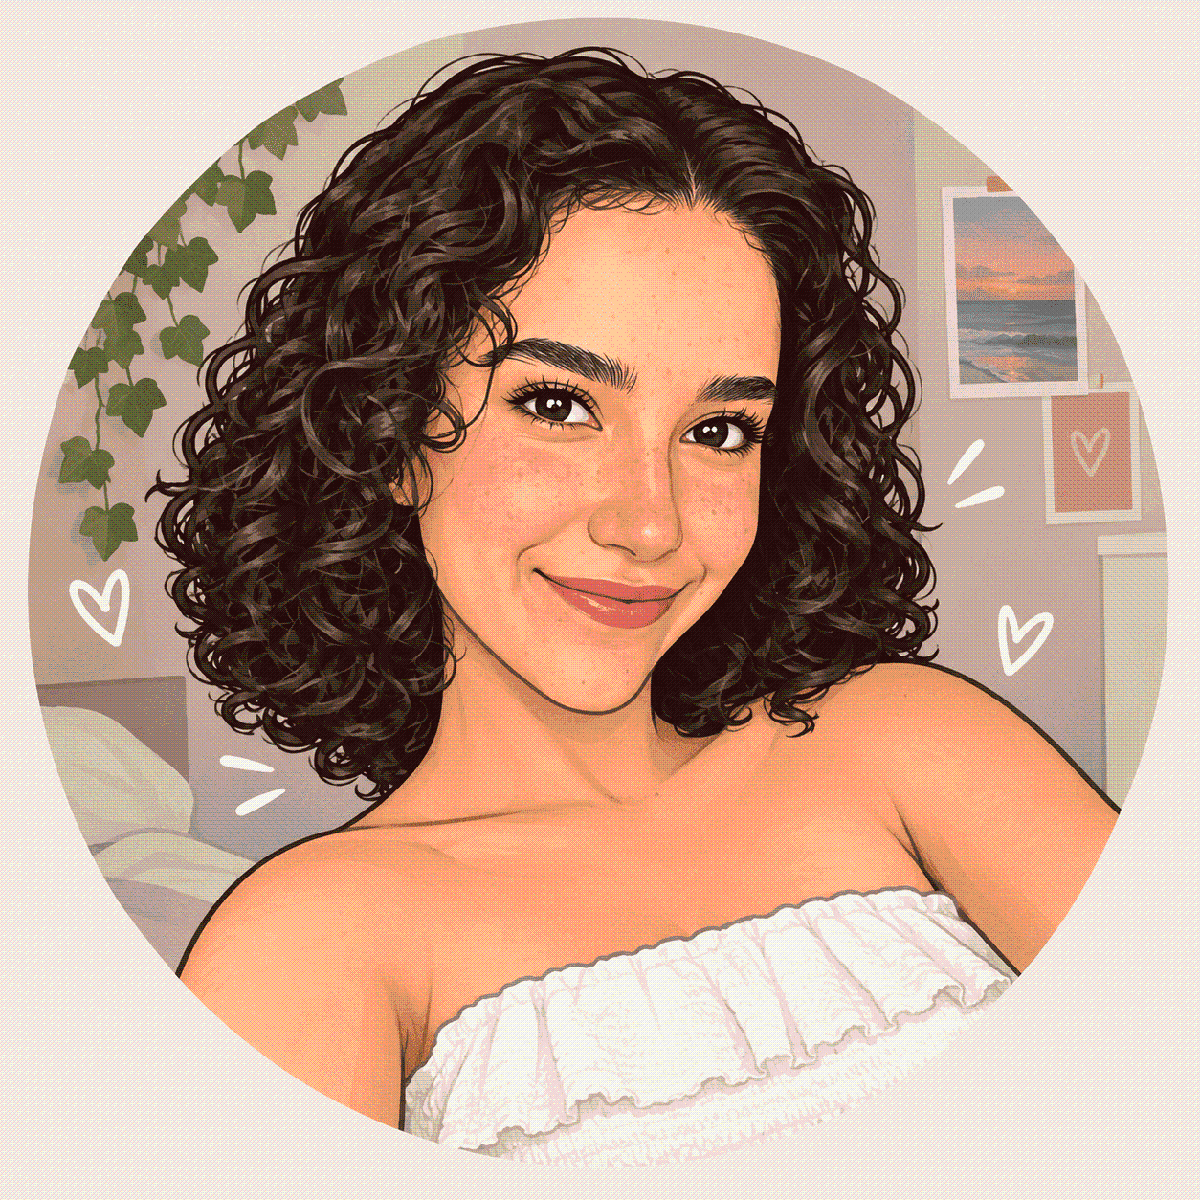

Nombre del alumno: Sara Gutiérrez Hernandez

Número de control: 23212734

Correo institucional: L23212734**@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
open_system('sistema3')
parameters.StopTime = '15';
parameters.Solver = 'ode15s';
parameters.MaxStep = '1e-2';
x = sim('sistema3', parameters);

t_data = (0:0.1:15)';
t = (0:0.001:15)';
Pa = interp1(t_data, x.Pa, t, 'previous');
writematrix(x.Pa, 'signal.xlsx');

## Respuestas: Hipotenso, Normotenso e Hipertenso

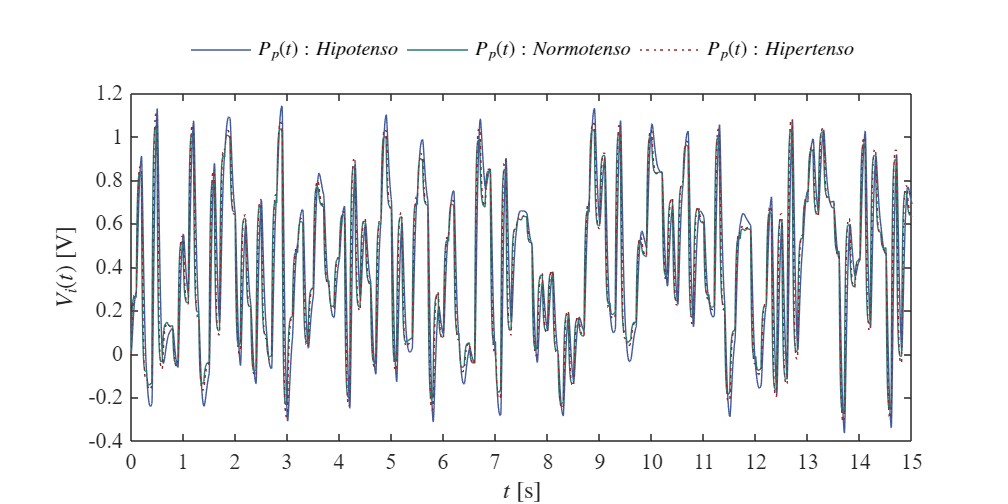

plotsignals(x.t,x.PpL,x.PpN,x.PpH,'individuos')

## Respuestas: Normotenso, Hipotenso y Controlador 

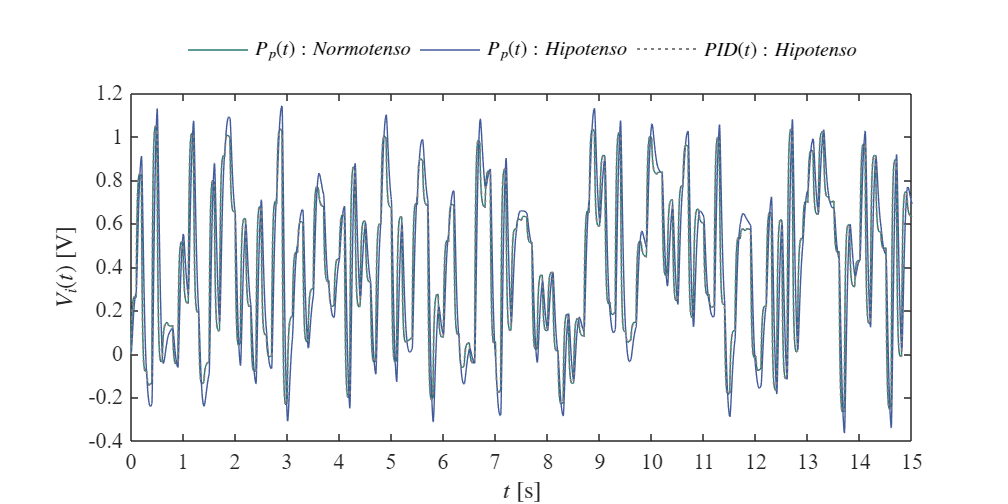

plotsignals(x.t,x.PpN,x.PpL,x.PIDL,'hipotenso')

## Respuestas: Normotenso, Hipertenso y Controlador

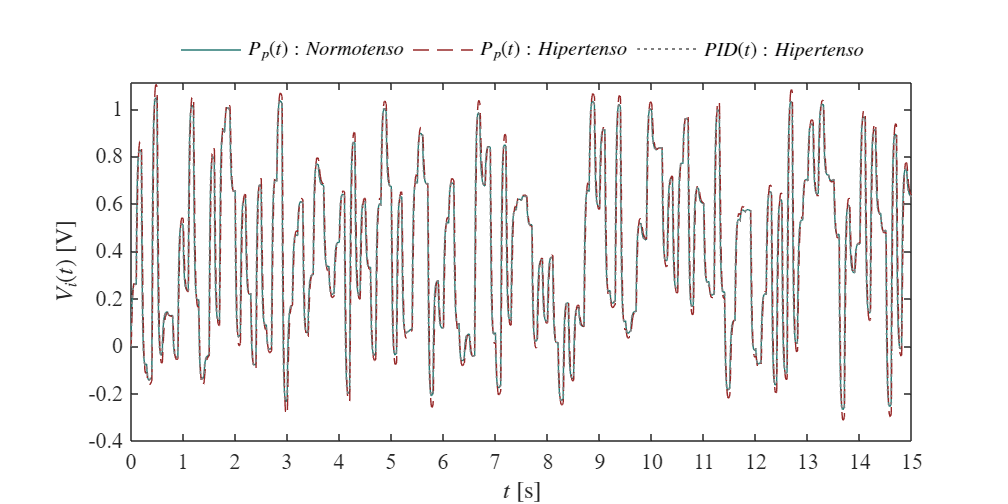

plotsignals(x.t,x.PpN,x.PpH,x.PIDH,'hipertenso')

## Modelo de EDOs

para_hipo = [0.01,0.001,1.00,3.500]; %[Z,L,R,C]
para_normo = [0.01,0.001,1.00,1.500];
para_hiper = [0.01,0.001,1.00,1.000];
PpN = cardio(para_normo,Pa,t);
PpL = cardio(para_hipo,PpN,t);
PpH = cardio(para_hiper,PpN,t);
plotsignals(x.t,x.PpL,x.PpN,x.PpH,'odes')


function Pp = cardio(par,Pa,t)
    Z = par(1); L = par(2); R = par(3); C = par(4); dt= t(2);
    n = round(t(end)/dt);
    FL = zeros(length(t),1); FL(1) = 0;
    Pp = zeros(length(t),1); Pp(1) = 0;
    for i =1:n
        FL(i+1) = FL(i) + (-Pp(i)/L + Pa(i)/L)*dt;
        Pp(i+1) = Pp(i) + (FL(i)/C - (1/(Z*C)+ 1/(R*C))*Pp(i) + Pa(i)/(Z*C))*dt;
    end
end

## Función: Respuesta de la simulación

function plotsignals(t,x1,x2,x3,caso)
   set (figure(), 'color', 'w')
   set (gcf, 'units', 'inches', 'position',[1,1,7,3.5])
   set (gca, 'fontname', 'times new roman','fontsize',11)
   hold on; grid off; box on;
   clr1 = [66, 91, 154]/255;
   clr2 = [40, 122, 116]/255;
   clr3 = [151, 40, 40]/255;
   clr4 = [0.5, 0.5, 0.5];

   if caso == "individuos"
        plot (t,x1,'-','LineWidth',0.25,'Color',clr1)
        plot (t,x2,'-','LineWidth',0.25,'Color',clr2)
        plot (t,x3,':','LineWidth',0.25,'Color',clr3)
        L = legend('$P_p(t): Hipotenso$','$P_p(t): Normotenso$','$P_p(t): Hipertenso$');
   elseif caso == "hipotenso"
        plot (t,x1,'-','LineWidth',0.25,'Color',clr2)
        plot (t,x2,'-','LineWidth',0.25,'Color',clr1)
        plot (t,x3,':','LineWidth',1,'Color',clr4)
        L = legend('$P_p(t): Normotenso$','$P_p(t): Hipotenso$','$PID(t): Hipotenso$');
   elseif caso == "hipertenso"
        plot (t,x1,'-','LineWidth',0.25,'Color',clr2)
        plot (t,x2,'--','LineWidth',0.25,'Color',clr3)
        plot (t,x3,':','LineWidth',1,'Color',clr4)
        L = legend('$P_p(t): Normotenso$','$P_p(t): Hipertenso$','$PID(t): Hipertenso$');
   elseif caso == "odes"
        plot (t,x1,'-','LineWidth',0.25,'Color',clr1)
        plot (t,x2,'-','LineWidth',0.25,'Color',clr2)
        plot (t,x3,':','LineWidth',0.25,'Color',clr3)
        L = legend('$P_p(t): Hipotenso$','$P_p(t): Normotenso$','$P_p(t): Hipertenso$');
   end
        
   set(L,'interpreter','latex','location','northoutside','orientation','horizontal','box','off')    
   xlabel('$t$ [s]','interpreter','latex')
   ylabel('$V_i(t)$ [V]','interpreter','latex')
        
   xlim([0 15]); xticks(0:1:15)
   ylim([-0.4 1.2]); yticks(-0.4:0.2:1.2)
   
   exportgraphics(gcf,[caso,'_matlab.pdf'],'contenttype','vector')
end

